%Preprocessing steps for orange_piece.jpg
orangePiece = double(imread("orange_piece.jpg"));
%Resize orangePiece to lower the resolution by a factor of 5
newOrangePieceRows = ceil(size(orangePiece,1)/5);
newOrangePieceCols = ceil(size(orangePiece,2)/5);
orangePiece = imresize(orangePiece,[newOrangePieceRows newOrangePieceCols]);
%Changing to grayScale
orangePiece = 0.2989*orangePiece(:,:,1)+0.5870*orangePiece(:,:,2)+0.1140*orangePiece(:,:,3);
%Removing noise from the image
orangePieceGray = medfilt2(orangePiece);
orangePiece = orangePieceGray > 100;
sum(orangePiece(:))

ans = 718

length(orangePiece(:))

ans = 4293

max(orangePiece(:))

ans = logical
   1


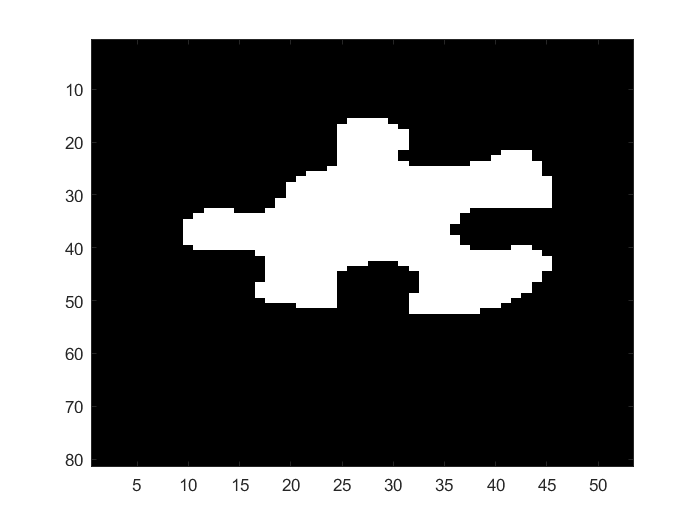


imagesc(orangePiece);
%Preprocessing steps for main.jpg
colormap('gray')

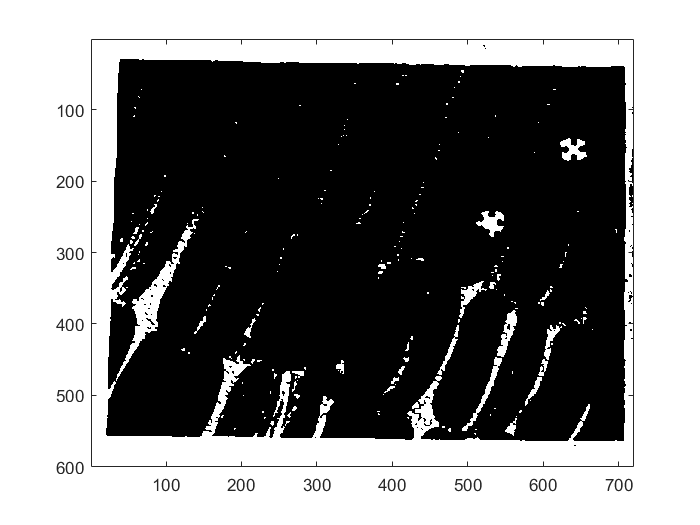

main = double(imread("main.jpg"));
%Resize main to lower the resolution by a factor of 5
newMainRows = ceil(size(main,1)/5);
newMainCols = ceil(size(main,2)/5);
main = imresize(main,[newMainRows newMainCols]);
%Changing to grayScale
main = 0.2989*main(:,:,1)+0.5870*main(:,:,2)+0.1140*main(:,:,3);
%Removing noise from the image
mainGray = medfilt2(main);
%Binarizing
main = mainGray < 35;
imagesc(main);

tic
costmin = intmax;
rowStartSol = 1;
rowEndSol = size(orangePiece,1);
colStartSol = 1;
colEndSol = size(orangePiece,2);
rotSol = 0;

allRotations = zeros(size(orangePiece,1),size(orangePiece,2),8);
allRotations(:,:,1) = orangePiece;

for rot=2:8
    angle = (rot-1)*45;
    allRotations(:,:,rot) = rotatePiece(orangePiece,angle);
end

%Initialize frame to the top left corner of main
rowStartConst = 1;
rowEndConst = size(orangePiece,1)-1;
colStartConst = 1;
colEndConst = size(orangePiece,2)-1;
PieceIntensity = sum(orangePiece(:));

for shiftRow=0:size(main,1)
    rowStart = rowStartConst + shiftRow;
    rowEnd = rowEndConst + rowStart;
    colEnd = size(orangePiece,2)-1;
    
    if (rowStart > 0) && (rowEnd <= size(main,1))
        for shiftCol=0:size(main,2)
            colStart = colStartConst + shiftCol;
            colEnd = colEndConst + colStart;
            if (colStart > 0) && (colEnd <= size(main,2))
                
                frame = main(rowStart:rowEnd,colStart:colEnd);
                frameIntensity = sum(frame(:));
                
                %Ignoring frames which have either <=50% or >=150% of the Piece Intensity,
                %Considering +/- 50% for noise data.
                
                if(frameIntensity<0.5*PieceIntensity || frameIntensity>1.5*PieceIntensity)
                    continue;
                end
                
                %Find cost
                costmat = (allRotations - frame).^2;
                cost = sum(sum(costmat));
                [Mini,Index] = min(cost);
                if(Mini<costmin)
                    costmin = Mini;
                    rowStartSol = rowStart;
                    rowEndSol = rowEnd;
                    colStartSol = colStart;
                    colEndSol = colEnd;
                    rotSol = Index;
                end
                
            else
                break;
            end
            
        end
    else
        break;
    end
    
end
toc

Elapsed time is 28.024069 seconds.


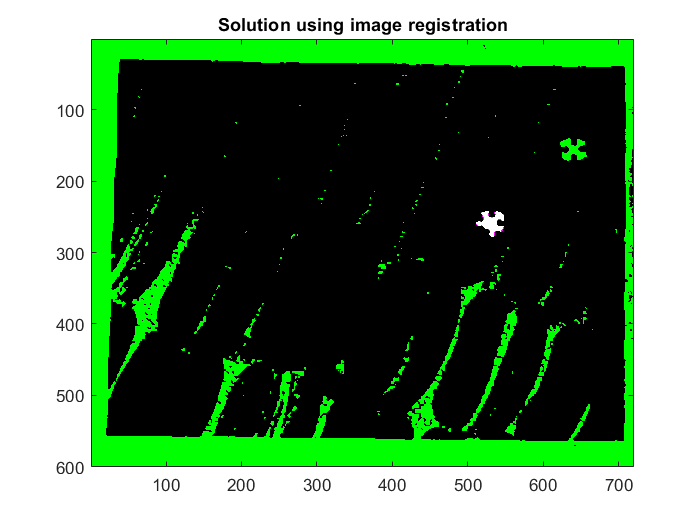

%Generating Image
generated_image = zeros(size(main));
generated_image(rowStartSol:rowEndSol,colStartSol:colEndSol) = allRotations(:,:,rotSol);

%Combining the images
fused_img = imfuse(main, generated_image);
figure
imagesc(fused_img);
title('Solution using image registration');

toc

Elapsed time is 28.151000 seconds.


%Function to rotate the puzzle piece

function rotimg = rotatePiece(piece,angle)
rotimg=zeros(size(piece));
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);
rotmat_inv=inv(rotmat);

shift=zeros(2,1);
shift(1,1)= floor(size(piece,1)/2);
shift(2,1)= floor(size(piece,2)/2);
rho=0;
for i=1:size(piece,1)
    for j=1:size(piece,2)
        newpix(1,1)=i;
        newpix(2,1)=j;
       	oldpix=round(rotmat_inv*(newpix-shift)+shift);
        if (oldpix(1,1) > 0) && (oldpix(1,1) < size(piece,1)) && (oldpix(2,1) > 0) && (oldpix(2,1) < size(piece,2))
            rho=piece(oldpix(1,1),oldpix(2,1));
        end
       	rotimg(i,j)=rho;
    end
end
end
